# 時空間相関Plotの作成

## ①beforeFit　②afterFit　③overlay (beforeFitとafterFit) 

folder_name_output = sprintf("output/%s/%s", DATE, beads_size)
if not(exist(folder_name_output,'dir'))
    mkdir(folder_name_output)
end

### ①beforeFit

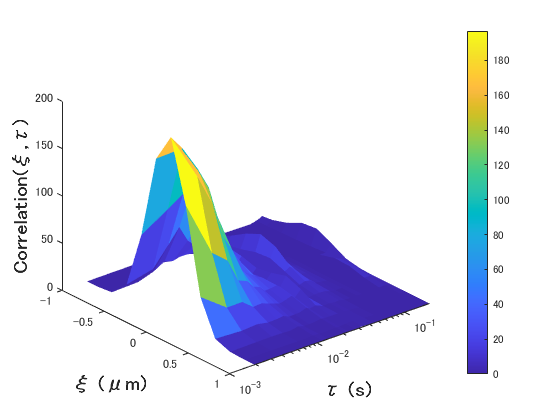

%plot
figure
s_beforeFit = surface(KSAI, TAU, COR);
s_beforeFit.EdgeColor = 'none';%これでメッシュ線なくなる
set(gca,'Yscale','log')
colorbar;
colormap;view(50,30);
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');
zlabel('Correlation(ξ,τ)','FontSize',14,'FontWeight','bold');
xlim([-1 1]);


%save figure
figurename = strrep(filename, ".lsm", ".fig");
saveas(gcf, sprintf("output/%s/%s/3D_beforeFit %s",DATE, beads_size, figurename))

### ②afterFit

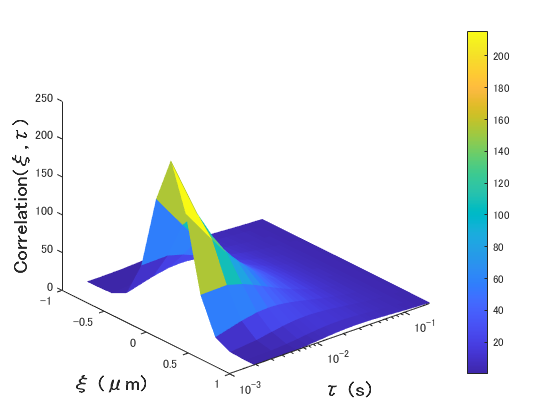

%plot
figure
s_afterFit = surface(KSAI,TAU, reshape(modelfun_3dim(parms, X), [size(COR,1), size(COR,2)]));
s_afterFit.EdgeColor = 'none';%これでメッシュ線なくなる
set(gca,'Yscale','log')
colorbar;
colormap;view(50,30);
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');
zlabel('Correlation(ξ,τ)','FontSize',14,'FontWeight','bold');
xlim([-1 1]);


%save figure
saveas(gcf, sprintf("output/%s/%s/3D_afterFit %s",DATE,beads_size, figurename))

### ③overlay

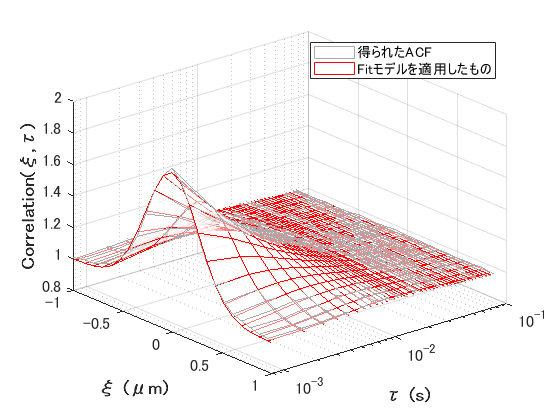

%plot
figure
s_beforeFit = surf(KSAI, TAU, COR,'FaceAlpha',0.5);
s_beforeFit.EdgeColor = '#AAAAAA';
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');
zlabel('Correlation(ξ,τ)','FontSize',14,'FontWeight','bold');

xlim([-1 1]);
set(gca,'Yscale','log')
view(50,30);
colormap("white")
ax = gca; % current axes
ax.FontSize = 12;

hold on;

s_afterFit = surf(KSAI,TAU, reshape(modelfun_3dim(parms, X), [size(COR,1), size(COR,2)]),'FaceAlpha',0.7);
s_afterFit.EdgeColor = 'red';
colormap("white")

hold off;
legend("得られたACF","Fitモデルを適用したもの", 'Location','northeast');


%save figure
saveas(gcf, sprintf("output/%s/%s/3D_overlay %s",DATE,beads_size, figurename))